# Playing with reference frames

Reference frames are created from a vector basis and an origin point. In Anakin, the class `frame` allows defining reference frames. 

As always, start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

We can think of the default frame as the canonical reference frame:

S = frame % default call

S = Frame with origin with coordinates:
     0
     0
     0

And basis with rotation matrix:
     1     0     0
     0     1     0
     0     0     1


A new reference frame can be created in multiple ways; the general rule is to give the origin point first, then the basis:

theta = 30*pi/180;
B = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1]);
O = point([1,2,3]);

S = frame(O,B) 

S = Frame with origin with coordinates:
     1
     2
     3

And basis with rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


One can also define a frame with respect to another frame, given as the last argument. Internally, the frame object stores only its origin position vector components and change of basis matrix with respect to the canonical basis:

phi = 30*pi/180;
B0 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
O0 = point([1,1,1]);
S0 = frame(O0,B0);

S1 = frame([1,2,3],[cos(theta),sin(theta),0;-sin(theta),cos(theta),0;0,0,1],S0)

S1 = Frame with origin with coordinates:
    2.0000
    4.2321
    2.5981

And basis with rotation matrix:
    0.8660    0.5000         0
   -0.4330    0.7500   -0.5000
   -0.2500    0.4330    0.8660


% Other forms of passing O and B are allowed, but not recommended 

For convenience, any object of frame class or a subclass can be passed as input. The result is converted to class frame:

S = frame; 
S = frame(S); 

## Basic functionality

To extract the origin or the basis of a reference frame, use the `origin` and `basis` methods:

S1.origin 

ans = Point with coordinates:
    2.0000
    4.2321
    2.5981


S1.basis 

ans = Basis with rotation matrix:
    0.8660    0.5000         0
   -0.4330    0.7500   -0.5000
   -0.2500    0.4330    0.8660


Finally, a numeric reference frame can be plotted using `plot`:

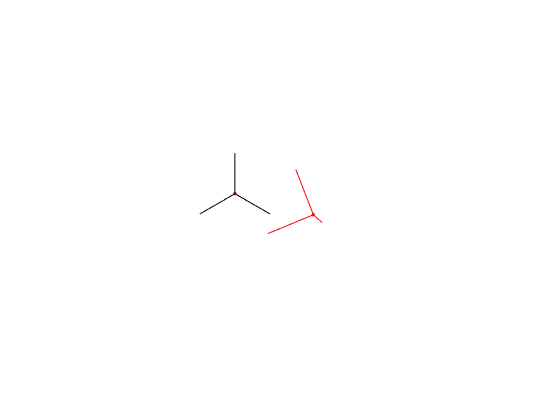

ax = axes('DataAspectRatio',[1,1,1]);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
view([2,2,2]);

S.plot;
S1.plot('color', 'r', 'facecolor','r'); % pass quiver3 plotting arguments to change color, style, etc.

## Symbolic reference frames

Symbolic reference frames with symbolic have additional functionality, inherited from `point` and `basis` classes (running this requires the Symbolic Math Toolbox installed):

syms t xi(t) theta(t); % declare symbolic variables
assume([in(t, 'real'), in(xi(t), 'real'), in(theta(t), 'real')]); 

B1 = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1]);
O1 = point([xi,0,0]); 
S1 = frame(O1,B1)

S1 = Frame with origin with coordinates:
 xi(t)
     0
     0
 
And basis with rotation matrix:
[ cos(theta(t)), -sin(theta(t)), 0]
[ sin(theta(t)),  cos(theta(t)), 0]
[             0,              0, 1]
 

To particularize a symbolic reference frame at particular values of its degrees of freedom, one may use `subs`, by specifying them in a list:

S1.subs({xi,theta},{2,pi/6}) % replace xi with 2 and theta with pi/6

ans = Frame with origin with coordinates:
     2
     0
     0

And basis with rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000
